# Rad229_EPI_Chemical_Shift_Demo.mlx demonstrates chemical shift effects in echo planar imaging (EPI).

% These questions can be used to further explore the code and concepts.

%     1) Why are chemical shift artifacts less pronounced at lower B0?

%     2) Silicone has a very different chemical shift (+4.5ppm) compared to fat. How does this effect chemical shift artifacts?

%     3) What is the effect of chemical shift artifacts on a center-out EPI trajectory?

%     4) [Advanced] Code up an example that demonstrates chemical shift artifacts from both fat and silicone in the same object.

%     5) [Advanced] Code up an example that includes a smooth distribution of fat off-resonance frequencies. How would you 

%     describe the image artifacts? See: https://onlinelibrary.wiley.com/doi/pdf/10.1002/jmri.21895

DBE@STANFORD.EDU (April 2021) for Rad229

## Default Parameters

% Define MRI system constants
sys = Rad229_MRI_sys_config;
sys.B0 = 0.1; 

% Acquisition parameters
acq.Nx = 128;                    % Matrix is NxM (then padded later to accomodate motion)
acq.ESP = 5000e-6;                % Echo spacing [s]

% Chemical shift parameters
obj.fat_ppm = -3.3e-6;                    % Chemical shift of fat [ppm];
% obj.silicone_ppm = +4.5e-6;               % Chemical shift of silicone implant [ppm]; https://onlinelibrary.wiley.com/doi/full/10.1002/jmri.22872
obj.dB0_fat = obj.fat_ppm * sys.B0;       % B0 shift [T]
obj.f_fat = sys.gamma_bar * obj.dB0_fat;  % Frequency offset [Hz]
obj.num = 3; % Identify the phantom sub-object for fat (default phantom has 11 objects)

## Generate the phantom object

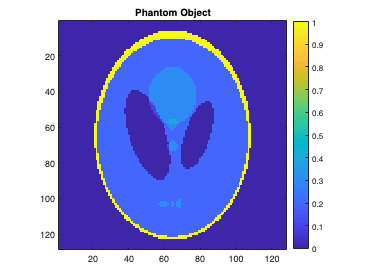

[ P , M ] = Rad229_MRI_Phantom( acq );
figure; imagesc(P); axis equal tight; title('Phantom Object'); 
  colorbar; caxis([0 1]);

## Create a WATER object and its k-space

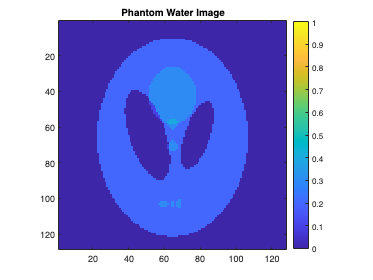

P_w = P .* ~M( : , : , obj.num ); % Assign everything to be WATER except FAT

kspc_w = fftshift( fft2(P_w) );   % Define the k-space
IM_w = ifft2( fftshift(kspc_w) ); % Image of WATER object

figure; imagesc( abs(P_w) ); axis equal tight; title('Phantom Water Image'); 
  colorbar; caxis([0 1]);

## Create a FAT object

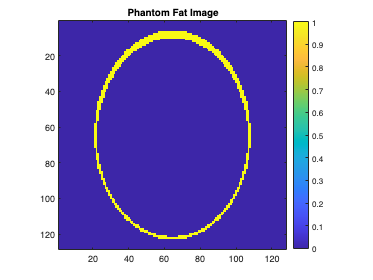

P_f = P .* M( : , : , obj.num );     % Create the fat part of the phantom object

% Replicate the FAT object for each echo time
P_f = repmat( P_f , [1 1 acq.Nx] );  % Create a phantom object for each echo time

% Add phase to the fat pixels for each echo
for n = 1 : acq.Nx
  phs_f = exp( -1i * 2 * pi * obj.f_fat * acq.ESP * n );  % Phase from fat per echo
  P_f( : , : , n ) = P_f( : , : , n ) .* phs_f; % Object accumulates phase during EPI duration
end

figure; imagesc( abs(P_f(:,:,1)) ); axis equal tight; title('Phantom Fat Image')
  colorbar; caxis([0 1]);

  
disp('Notice the phase accumulation in the FAT for each echo.')

Notice the phase accumulation in the FAT for each echo.


disp('The linear (with time) phase shift accords with...');

The linear (with time) phase shift accords with...


disp('...a linear phase shift during acquistion.');

...a linear phase shift during acquistion.


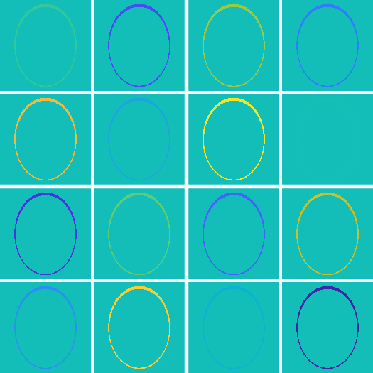

% tmp = P_w + P_f( : , : , 1 : 8 : end );
tmp = P_f( : , : , 1 : 8 : end );
figure; imagescn( angle(tmp) , [-pi pi] ); colormap("parula"); axis equal tight;

## Create a FAT object's k-space for each echo time

kspc_f = zeros( size(P_f) );
for n = 1 : acq.Nx
  kspc_f( : , : , n ) = fftshift( fft2( P_f( : , : , n ) ) );
end

## Simulate the TOP-DOWN EPI Trajectory

kspc_f_epi = zeros( acq.Nx );

% Grab one echo per ky-line during fat phase accumulation
for n = 1 : acq.Nx
  kspc_f_epi( n , : ) = kspc_f( n , : , n ); % Fill the nth-row with the nth-row from the nth-phase
end
IM_f = ifft2( fftshift(kspc_f_epi) );  % Image of FAT object

%% The FT is a linear operator so we can add the k-space or the images
IM_CS = IM_w + IM_f + ( randn( size(IM_w) ) + 1i * randn( size(IM_w) ) ) / 25;

## Create a Figure

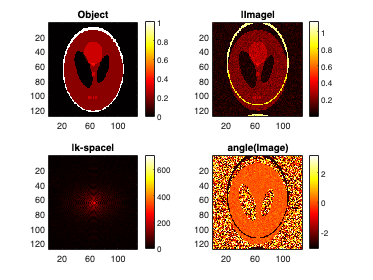

figure; hold on; colormap(hot);
  subplot(2,2,1); imagesc(abs(P));  title('Object');  colorbar;
  subplot(2,2,2); imagesc(abs(IM_CS));  title('|Image|');   colorbar;
  subplot(2,2,3); imagesc(abs(kspc_f_epi));  title('|k-space|');   colorbar;
  subplot(2,2,4); imagesc(angle(IM_CS));  title('angle(Image)'); colorbar;